**BORN APPROXIMATION - TSVD IMAGING**

This script implements a microwave imaging algorithm based on the Born approximation and Truncated Singular Value Decomposition (TSVD). The scattered field data is inverted to recover the complex dielectric contrast profile inside the Domain of Interest (DOI).

The reconstruction pipeline follows five steps:

- Load the background field, geometry, and scattered field datasets

- Build the data operator $K$ using the Born approximation

- Decompose $K$ via the Singular Value Decomposition

- Regularize the inversion with the TSVD energy threshold

- Visualize the recovered dielectric contrast profile

clc;
close all;
clear;

**LOAD DATA**

Three data files are required:

-   background_fields.mat    :    Ecells (incident field at DOI cells), current, freq

-   geometry.mat                  :    mesh topology, probe indices, DOI cell index mask

-   scattered_fields.mat        :    scattered field at probes

BCK_FIELD   = load("../../Forward_solvers/results/background_fields.mat");
GEO         = load("../../Forward_solvers/results/geometry.mat");
DATA_FIELDS = load("../../Forward_solvers/results/scattered_fields.mat");

**DATA PREPARATION**

The following quantities are extracted:

-   E_sc             :    scattered field matrix (N_ant x N_ant), E_sc = Et - Ei at probe nodes

-   dV                 :    area of each DOI cell

-   E_inc_doi     :    incident electric field at all DOI cell centroids for every transmitter

-   I_ampere      :    excitation current amplitude

-   freq               :    operating frequency (Hz)

E_sc        = DATA_FIELDS.Eprobes_t - DATA_FIELDS.Eprobes_i;
dA          = GEO.Area(GEO.Ind_cells_doi, :);
E_inc_doi   = BCK_FIELD.Ecells(GEO.Ind_cells_doi, :);
I_ampere    = BCK_FIELD.current;
freq        = BCK_FIELD.freq;

**BUILD DATA OPERATOR K**

Under the Born approximation the scattered field at receiver r_rx due to transmitter r_tx is:

- 
$$\[
E_{sc}(r_{rx}, r_{tx})
=
\frac{j\omega}{I}
\sum_{r}
E_{inc}(r, r_{tx})
\,
E_{inc}(r_{rx}, r)
\,
\chi(r)
\,
dA(r)
\]$$


Assembling all transmitter-receiver pairs into matrix form gives the linear system:

- 
$$\[
[E_{sc}]
=
[K] \, [\chi]
\]$$


where $K$ is the (N_meas x N_DOI) data operator and $\chi$ is the unknown contrast vector. Only the upper-triangular $(t_x.r_x)$ index pairs are retained to exploit array symmetry and avoid redundancy.

N_ant    = size(E_sc, 1);
Mmask    = triu(true(N_ant), 0);
[rr, cc] = find(Mmask);

A_tx = E_inc_doi(:, rr);
A_rx = E_inc_doi(:, cc);

K = (1i*2*pi*freq / I_ampere) * (A_tx.' .* A_rx.') .* dA';

**SINGULAR VALUE DECOMPOSITION**

The economy SVD factorises the data operator as:

- 
$$\[
K = U \, S \, V^{H}
\]$$


where:

-   $U$    :    left singular vectors (data space)

-   $S$    :    diagonal matrix of singular values in descending order

-   $V$    :    right singular vectors (model space)

[U, S, V] = svd(K, "econ");

**TRUNCATION CRITERION**

The singular spectrum of $K$ decays rapidly; high-index values carry noise and ill-conditioning. An energy-based threshold Th is applied: the smallest index Nt is found such that the cumulative squared singular value energy reaches 99.99% of the total.

Th         = 0.9999;
S2         = S .^ 2;
cum_energy = cumsum(S2) / sum(S2);
Nt         = find(cum_energy >= Th, 1, "first");



fprintf("Retaining %d of %d singular values (%.1f%% energy threshold)\n", Nt, size(S,1), Th*100);

Retaining 201 of 300 singular values (100.0% energy threshold)



% Truncated factors
U_r = U(:, 1:Nt);
S_r = S(1:Nt, 1:Nt);
V_r = V(:, 1:Nt);

**TSVD SOLUTION**

The contrast vector k_vec is recovered by applying the truncated pseudo-inverse to the vectorised observations e_sc (upper-triangular entries of E_sc):

- 
$$\[
\chi = V_r \, S_r^{-1} \, U_r^{H} \, e_{sc}
\]$$


Dividing by eps0 converts from absolute complex permittivity contrast to relative permittivity contrast.

eps0  = 8.854e-12;
E_sc  = E_sc(sub2ind([N_ant, N_ant], cc, rr));
chi = V_r * (S_r \ (U_r' * E_sc));
eps = chi ./ eps0;

**DIELECTRIC CONTRAST IMAGE**

The recovered contrast is rendered as a cell-wise constant patch plot over the DOI triangulation:

-   real(eps)    :    real part of relative permittivity contrast  ($\varepsilon^{'}$)

-   imag(eps)    :    imaginary part of relative permittivity contrast  ($\varepsilon^{''}$)

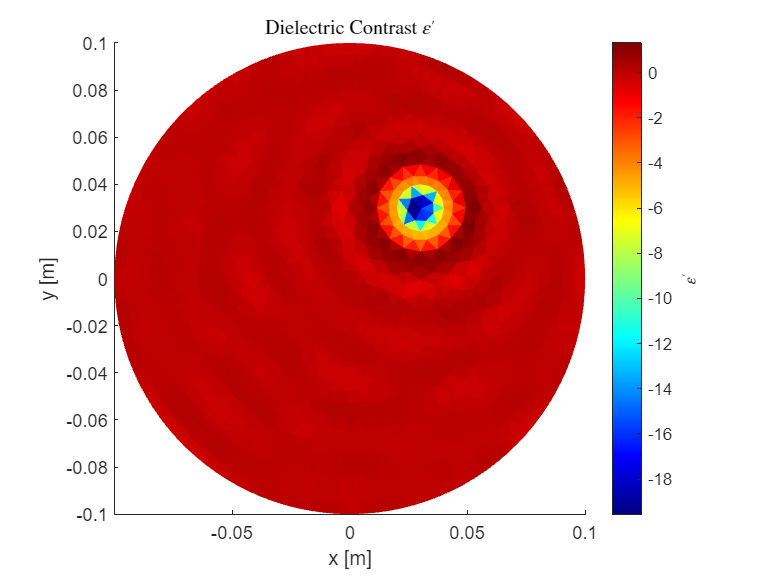

verts = GEO.verts(:, 1:2);
cells = GEO.cells(GEO.Ind_cells_doi, :);

% Real part -- epsilon prime
figure;
patch("Faces", cells, ...
      "Vertices", verts, ...
      "FaceVertexCData", real(eps), ...
      "FaceColor", "flat", ...
      "EdgeColor", "none");
axis equal tight;
cb = colorbar;
cb.Label.String    = "$\varepsilon'$";
cb.Label.Interpreter = "latex";
colormap jet;
title("Dielectric Contrast $\varepsilon'$","Interpreter","latex");
xlabel("x [m]");
ylabel("y [m]");

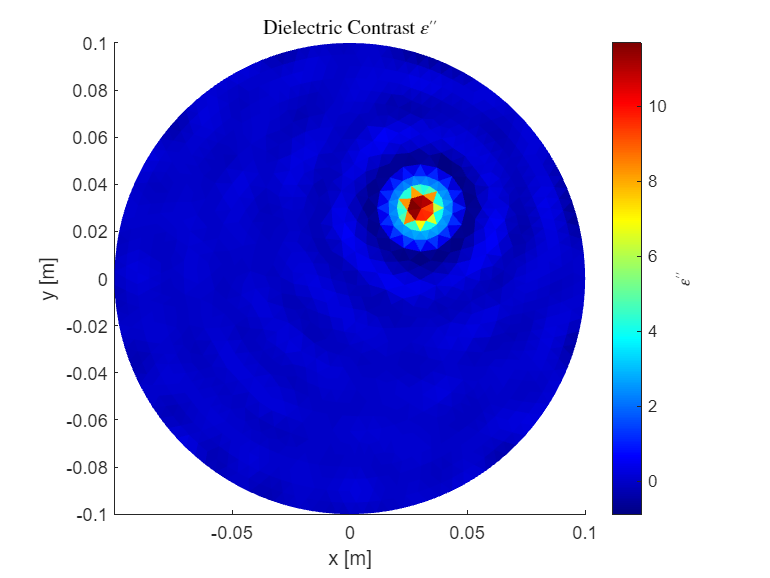


% Imaginary part -- epsilon double prime
figure;
patch("Faces", cells, ...
      "Vertices", verts, ...
      "FaceVertexCData", imag(eps), ...
      "FaceColor", "flat", ...
      "EdgeColor", "none");
axis equal tight;
cb = colorbar;
cb.Label.String    = "$\varepsilon''$";
cb.Label.Interpreter = "latex";
colormap jet;
title("Dielectric Contrast $\varepsilon''$","Interpreter","latex");
xlabel("x [m]");
ylabel("y [m]");